# Aufgabe 6:

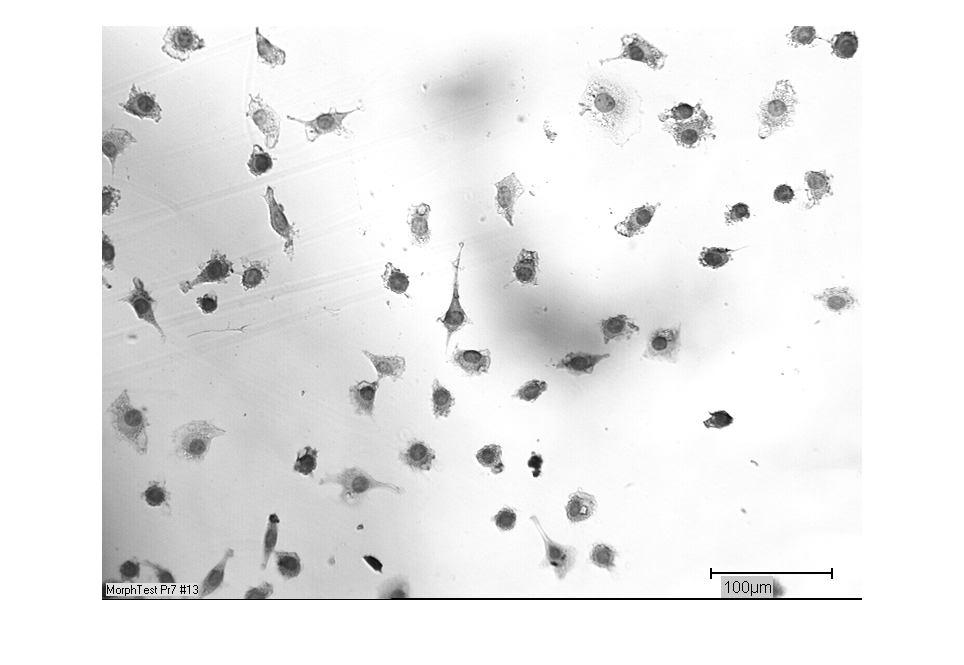

img = imread("cells.png");
imshow(img)


str = strel('disk', 11)

str = strel is a disk shaped structuring element with properties:

      Neighborhood: [21×21 logical]
    Dimensionality: 2


Filtering the Background

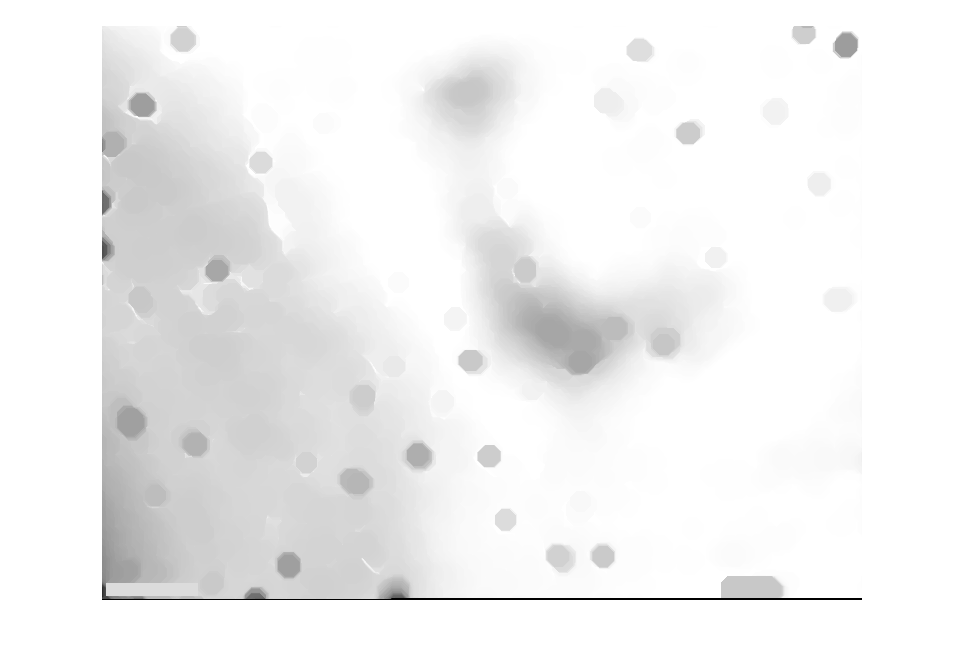

background = imclose(img,str);
imshow(background)

Subtracting the Background

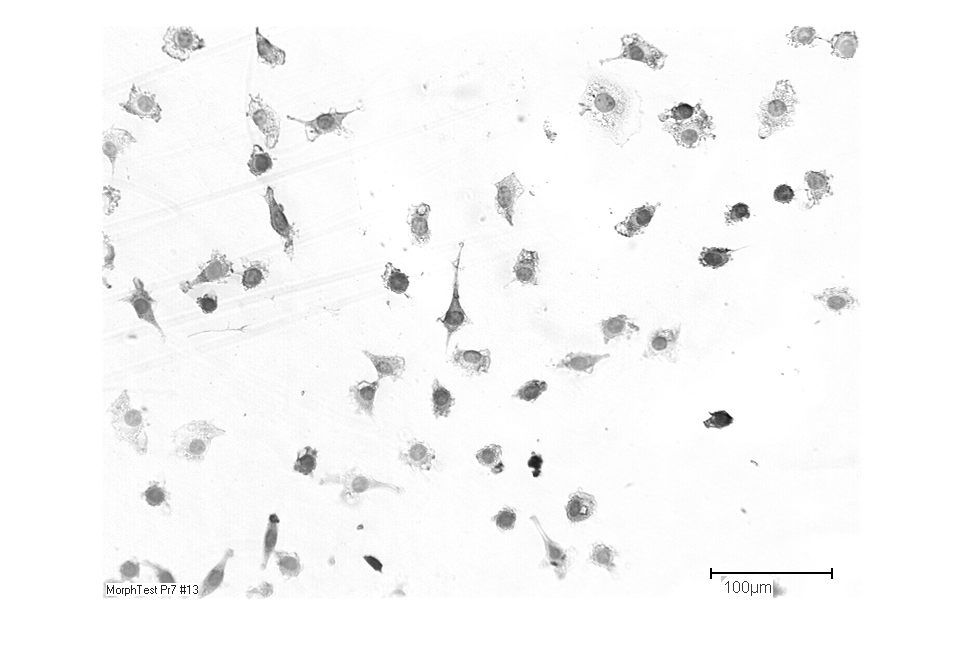

img2 = imcomplement(background - img);
imshow(img2)

Change to 8-bit Grayscale image

imgG = im2gray(img2);
imshow(imgG)

Change to Binary image

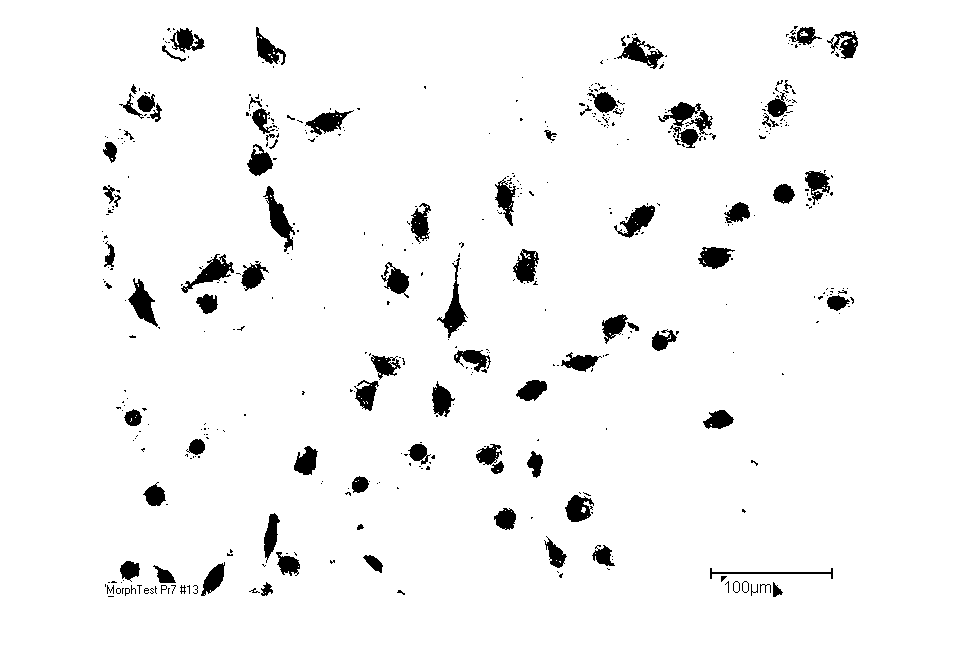

imgB = imbinarize(imgG);
imshow(imgB)

Opening with 3x3 structure element of ones

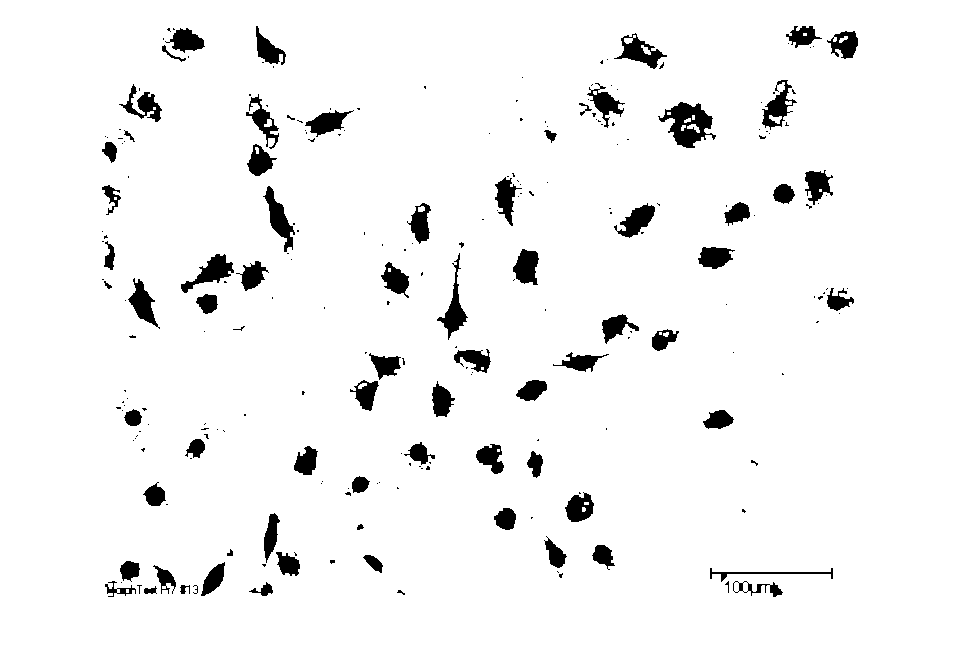

strSquare = strel('square', 3);
imgOpening = imopen(imgB, strSquare);
imshow(imgOpening)

Closing with disk structure element of radius 4

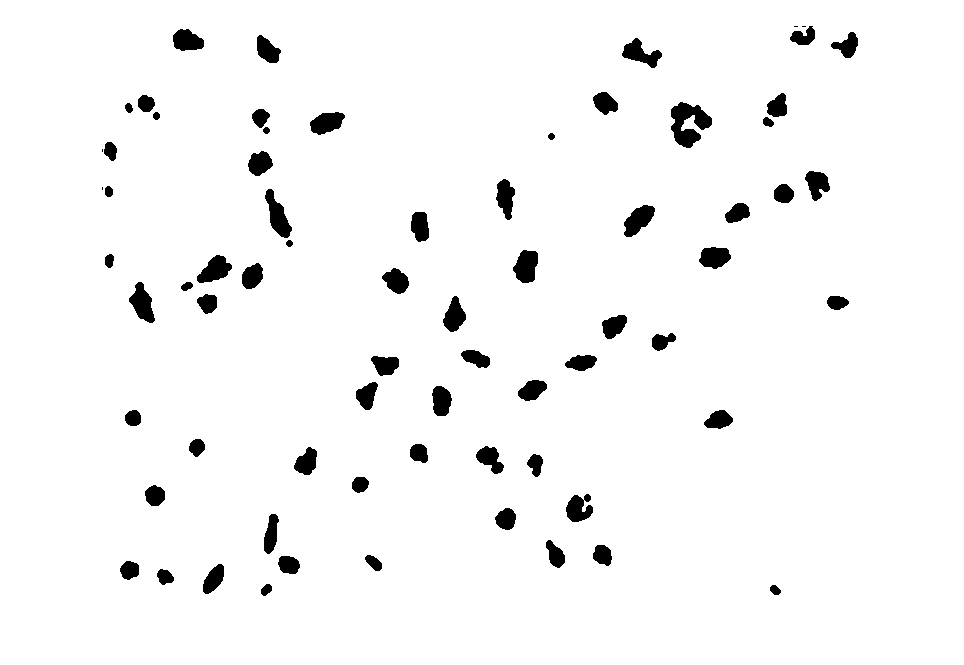

strDisk = strel('disk', 4);
imgClosing = imclose(imgOpening, strDisk);
imshow(imgClosing)

Overlay over original Image

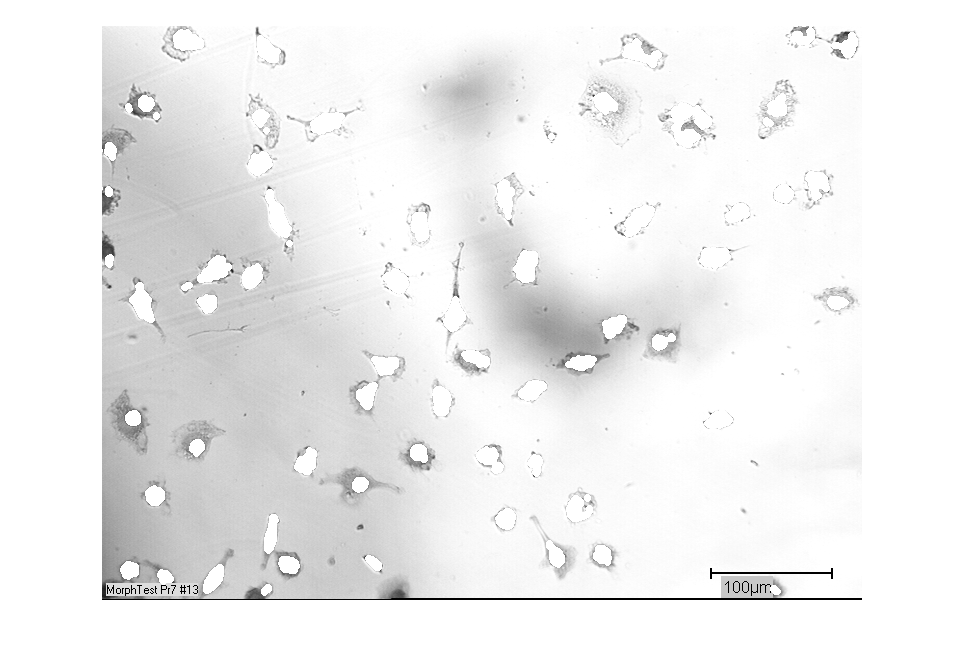

imgOverlay = img + uint8(imcomplement(imgClosing)) * 255;
imshow(imgOverlay)

Creating Labels

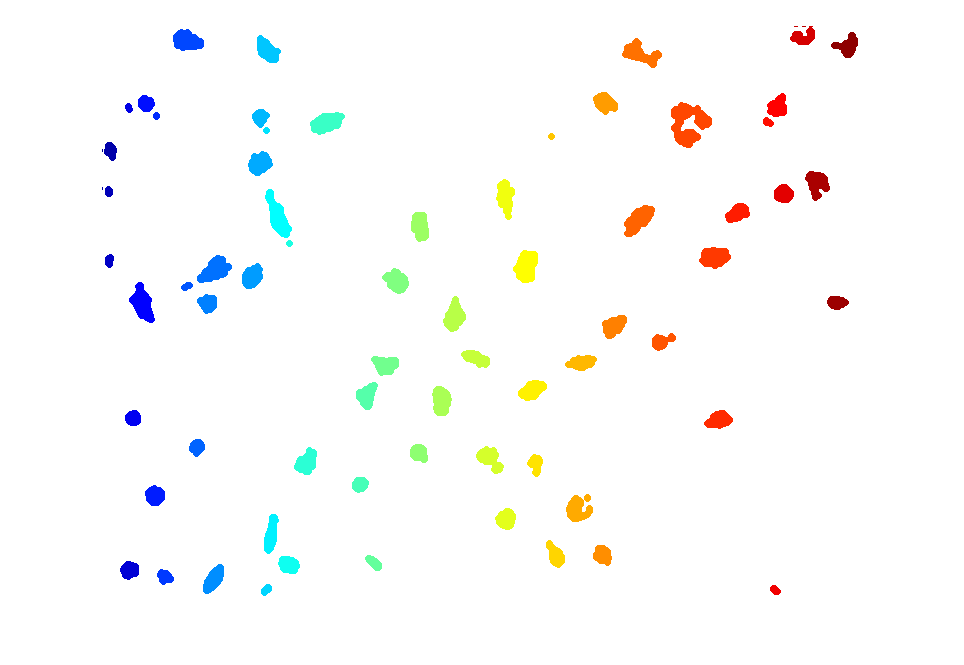

BW = imbinarize(uint8(imcomplement(imgClosing)));
CC = bwconncomp(BW);
L = labelmatrix(CC);

RGB = label2rgb(L);
imshow(RGB)

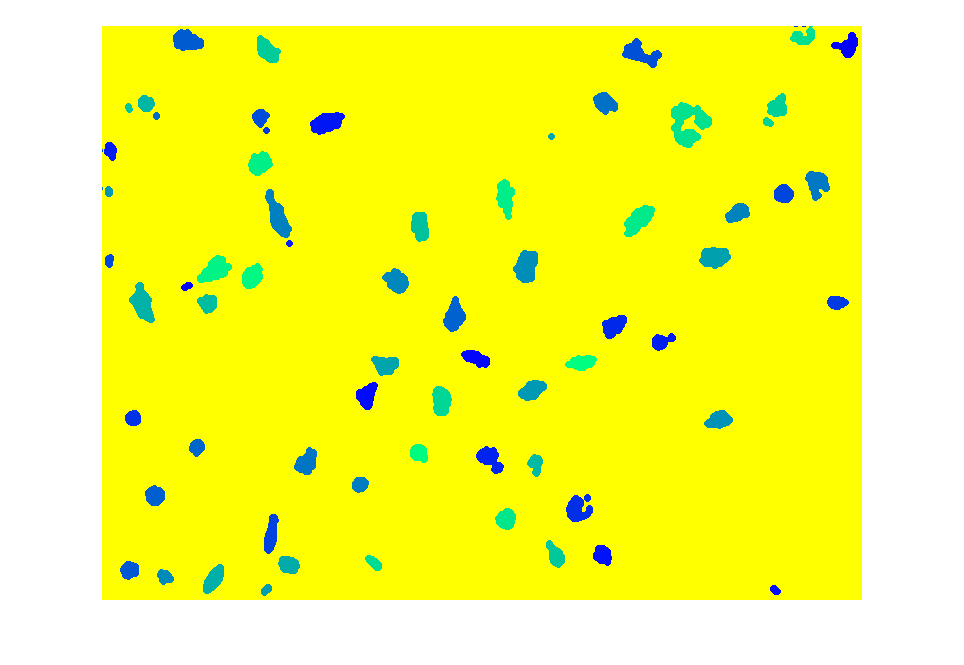


RGB2 = label2rgb(L,'winter','y','shuffle'); 
imshow(RGB2)


RP = regionprops(CC, 'Basic');
RP(10)

ans = struct with fields:
           Area: 224
       Centroid: [44.6607 78.0580]
    BoundingBox: [36.5000 69.5000 17 17]
